# Identify a SINDy model on synthetic Lorenz system data

- Lorenz system dynamics: 

                     
$$\begin{array}{l}
\dot{x} =\sigma \;\left(y-x\right)\\
\dot{y} =x\left(\rho -z\right)-y\\
\dot{z} =\textrm{xy}-\beta \;z
\end{array}$$


- Generate noisy data: integrate Lorenz system ODE and add Gaussian white noise

- Compute derivatives: using finite difference

- Build library

- Compute sparse regression

- Evaluate performance of SINDy model for forecasting

addpath(genpath(pwd))

## Generate Data

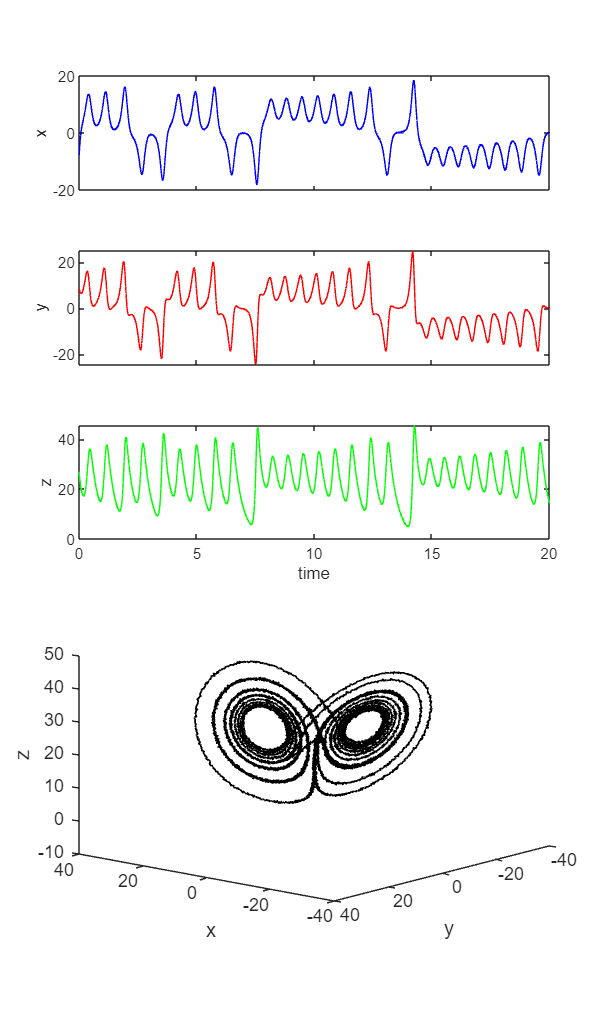

param = [10; 28; 8/3]; % Lorenz system parameters (chaotic)
n = 3; % number of states
x0 = [-8; 8; 27];  % Initial condition
dt = 0.001; % time step
tspan = dt:dt:20; 
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,3));
[t,x]=ode45(@(t,x) lorenz(t,x,param),tspan,x0,options);

% Add Gaussian white noise
rng(1)
sig = 0.01; 
x = x + sig*std(x(:))*randn(size(x)); 

plotLorenz(t,x) % plot data

% animateLorenz(t,x) % animate data


## Compute Derivative: finite difference

% fourth order central difference
dx = (1/(12*dt))*(-x(5:end,:)+8*x(4:end-1,:)-8*x(2:end-3,:)+x(1:end-4,:)); 

x = x(3:end-2,:); % cut tails
t = t(3:end-2,:);


## Pool Data (i.e., build library of nonlinear time series)

polyorder = 3; % polynomials up to order 3
Theta = poolData(x,n,polyorder);
m = size(Theta,2); % size of library


## Compute sparse regression: sequential thresholded least squares

lambda = 0.2; % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp(poolDataLIST({'x','y','z'},Xi,n,polyorder)) % display SINDy model

    {0×0 char}    {'xdot'   }    {'ydot'   }    {'zdot'   }
    {'1'     }    {[      0]}    {[      0]}    {[      0]}
    {'x'     }    {[-9.9810]}    {[27.8203]}    {[      0]}
    {'y'     }    {[ 9.9855]}    {[-0.9457]}    {[      0]}
    {'z'     }    {[      0]}    {[      0]}    {[-2.6649]}
    {'xx'    }    {[      0]}    {[      0]}    {[      0]}
    {'xy'    }    {[      0]}    {[      0]}    {[ 0.9992]}
    {'xz'    }    {[      0]}    {[-0.9958]}    {[      0]}
    {'yy'    }    {[      0]}    {[      0]}    {[      0]}
    {'yz'    }    {[      0]}    {[      0]}    {[      0]}
    {'zz'    }    {[      0]}    {[      0]}    {[      0]}
    {'xxx'   }    {[      0]}    {[      0]}    {[      0]}
    {'xxy'   }    {[      0]}    {[      0]}    {[      0]}
    {'xxz'   }    {[      0]}    {[      0]}    {[      0]}
    {'xyy'   }    {[      0]}    {[      0]}    {[      0]}
    {'xyz'   }    {[      0]}    {[      0]}    {[      0]}
    {'xzz'   }    {[      0]}    {[     

## Use SINDy model for prediction

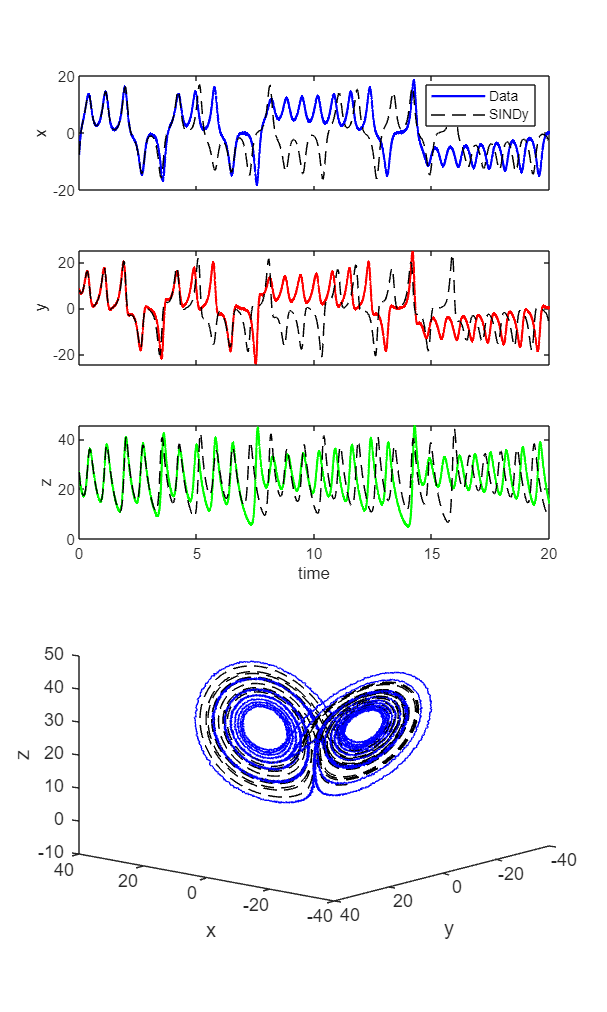

paramSINDy.Xi = Xi;
paramSINDy.polyorder = polyorder;
[tSINDy,xSINDy]=ode45(@(t,x) SINDyODE(t,x,paramSINDy),tspan,x0,options);

plotSINDy(t,x,tSINDy(3:end-2,:),xSINDy(3:end-2,:))